clear all
file_start=277;
file_end=326;
OD_raw_list=zeros(200,200,((file_end-file_start)+1));
for i=1:((file_end-file_start)+1)
    load(['\\Artemis-pc\e\Data\2023-10-19\Abs-',num2str(file_start+i-1),...
        '\OD_FR_2.mat']);
    OD_raw_list(:,:,i)=OD_FR;
end

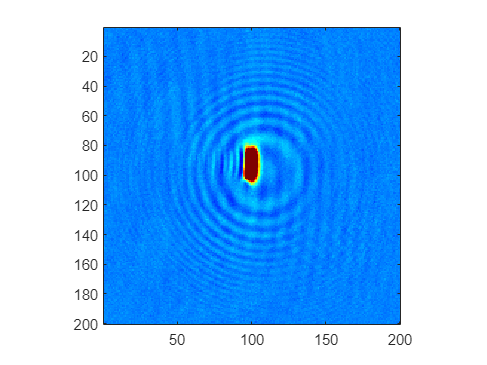

OD_average=mean(OD_raw_list,3);
figure
imagesc(OD_average)
colormap jet
clim([-0.1 0.3])
daspect([1,1,1])

file_start=259;
file_end=283;
OD_raw_list_2=zeros(300,1000,((file_end-file_start)+1));
for i=1:((file_end-file_start)+1)
    load(['\\Artemis-pc\e\Data\2023-10-08\Abs-',num2str(file_start+i-1),'\OD_FR_2.mat']);
    OD_raw_list_2(:,:,i)=OD_FR;
end

OD_average_2=mean(OD_raw_list_2,3);
figure
imagesc(OD_average_2)
colormap jet
clim([-0.1 0.3])
daspect([1,1,1])

OD_compare=OD_average+OD_average_2;
OD_compare_rotate=imrotate(OD_compare,1,'bilinear','crop');

figure
imagesc(OD_compare)
colormap jet
clim([-0.1 0.3])
daspect([1,1,1])

figure
imagesc(OD_compare_rotate)
colormap jet
clim([-0.1 0.3])
daspect([1,1,1])
axis off

figure
hold on
ODT_up=OD_compare_rotate(141,:);
ODT_down=OD_compare_rotate(162,:);
position=(1:1000)*6.5/1000;
plot(position,ODT_up)
plot(position,ODT_down)
box on
xlabel('Position (mm)')
ylabel('OD')

tile=tiledlayout(6,1,'TileSpacing','Compact','Padding','Compact');
nexttile(1,[5,1])
imagesc(OD_compare_rotate)
colormap jet
clim([-0.1 0.3])
daspect([1,1,1])
axis off
nexttile(6)
hold on
plot(position,ODT_up)
plot(position,ODT_down)
box on
xlabel('Position (mm)')
ylabel('OD')
set(gca,'FontSize',14)


clear all
file_start=339;
file_end=388;
OD_raw_list=zeros(200,200,((file_end-file_start)+1));
for i=1:((file_end-file_start)+1)
    load(['\\Artemis-pc\e\Data\2023-10-10\Abs-',num2str(file_start+i-1),'\OD_FR_2.mat']);
    OD_raw_list(:,:,i)=OD_FR;
end

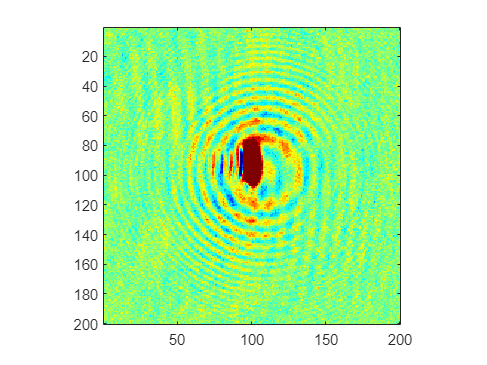

OD_average=mean(OD_raw_list,3);
figure
imagesc(OD_average)
colormap jet
clim([-0.05 0.05])
daspect([1,1,1])

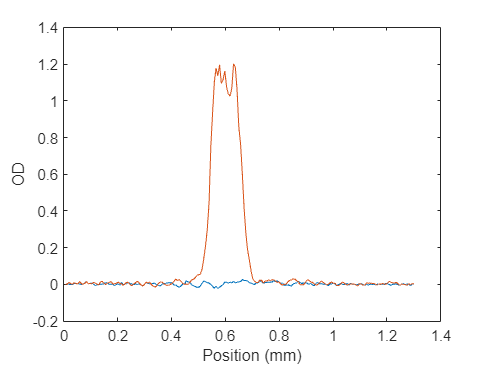


figure
ODT_H=sum(OD_average,1);
ODT_V=sum(OD_average,2);
ODT_H=OD_average(56,:);
ODT_V=OD_average(:,100);
OD_average(56,:)=100;
OD_average(:,100)=100;


position=(1:200)*6.5/1000;
hold on
plot(position,ODT_H)
plot(position,ODT_V)
box on
xlabel('Position (mm)')
ylabel('OD')

tile=tiledlayout(4,4,'TileSpacing','Compact','Padding','Compact');

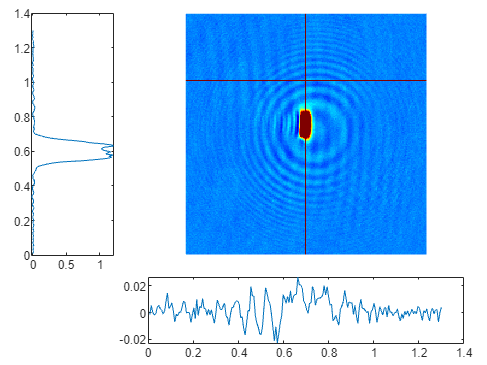

nexttile(1,[3,1])
plot(ODT_V,position)


nexttile(2,[3,3])
imagesc(OD_average)
axis off
colormap jet
clim([-0.1 0.3])
daspect([1,1,1])
nexttile(14,[1,3])
plot(position,ODT_H)

clear all
file_start=137;
file_end=186;
OD_raw_list=zeros(200,1000,((file_end-file_start)+1));
for i=1:((file_end-file_start)+1)
    load(['\\Artemis-pc\e\Data\2023-10-10\Abs-',num2str(file_start+i-1),'\OD_FR_2.mat']);
    OD_raw_list(:,:,i)=OD_FR;
end

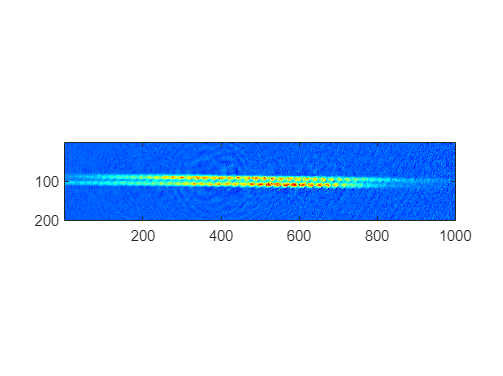

OD_average=mean(OD_raw_list,3);
figure
imagesc(OD_average)
colormap jet
clim([-0.1 0.3])
daspect([1,1,1])

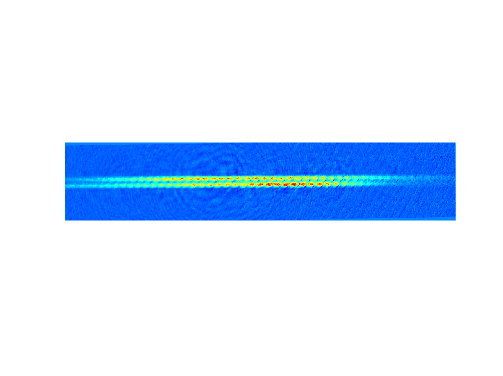


OD_compare_rotate=imrotate(OD_average,1,'bilinear','crop');

figure
imagesc(OD_compare_rotate)
colormap jet
clim([-0.1 0.3])
daspect([1,1,1])
axis off

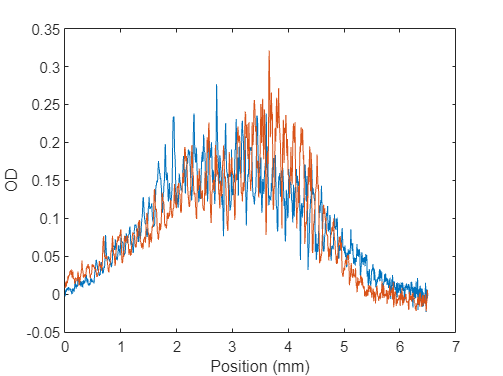


figure
hold on
ODT_up=OD_compare_rotate(93,:);
ODT_down=OD_compare_rotate(109,:);
position=(1:1000)*6.5/1000;
plot(position,ODT_up)
plot(position,ODT_down)
box on
xlabel('Position (mm)')
ylabel('OD')

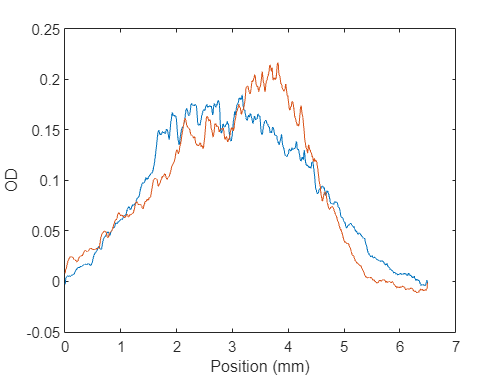


figure
hold on
ODT_up=OD_compare_rotate(93,:);
ODT_down=OD_compare_rotate(109,:);
position=(1:1000)*6.5/1000;
plot(position,smooth(ODT_up,20))
plot(position,smooth(ODT_down,20))
box on
xlabel('Position (mm)')
ylabel('OD')

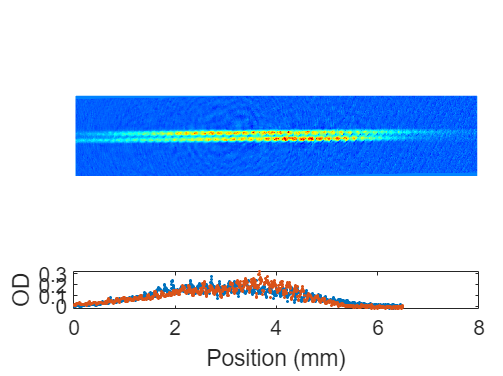

tile=tiledlayout(6,1,'TileSpacing','Compact','Padding','Compact');
nexttile(1,[5,1])
imagesc(OD_compare_rotate)
colormap jet
clim([-0.1 0.3])
daspect([1,1,1])
axis off
nexttile(6)
hold on
plot(position,ODT_up,'.')
plot(position,ODT_down,'.')
box on
xlabel('Position (mm)')
ylabel('OD')
set(gca,'FontSize',14)